# Stima con multisinusoidi e senza il system identification toolbox

Spesso in contesto industriale non è possibile usare il system identification toolbox. Vedremo qui come stimare la risposta in frequenza direttamente dalla definizione di serie di Fourier.

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1440, 792, 2240, 1680]); % figure più grandi
st=1e-3;
model=ElasticTransmission(st);
cs=ControlledSystem(model);

Definisco l'azione di controllo come una somma di portante e una sommatoria di sinusoidi. Le sinusoidi devono avere frequenza multipla di quella della portante.

#### Portante

omega_portante=0.05;
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=1.5*sin(omega_portante*t);

#### Multisinusoidi:

vettore della pulsazioni

omega=logspace(log10(5),log10(3000),60)';

arrotondo a dei multipli della portante

omega=round(omega/omega_portante)*omega_portante; % arrotondo per avere le omega multiple della portante

Rimuovo duplicati

omega=unique(omega); %scarto eventuali doppioni

Credo il segnale come somma di sinusoidi (qui suppongo ampiezza costante per ogni pulsazione, nulla mi impedisce di fare diversamente)

multisine_signal=zeros(length(t),1);
for idx=1:length(omega)
    multisine_signal=multisine_signal+sin(omega(idx)*t);
end

Impongo che l'ampiezza del segnale sia quella desiderata

max_applitude=2;
multisine_signal=multisine_signal/max(multisine_signal)*max_applitude;

Sommo i due segnali

control_action=portante+ multisine_signal;

Calcolo i coefficienti di Fourier dell'ingresso

control_action_coef=fourierCoefficients(t,control_action,omega_portante,omega);

Simulo il sistema

cs.initialize
for idx=1:length(t)
    [process_output(idx,:),t(idx,1)]=cs.openloop(control_action(idx));
end

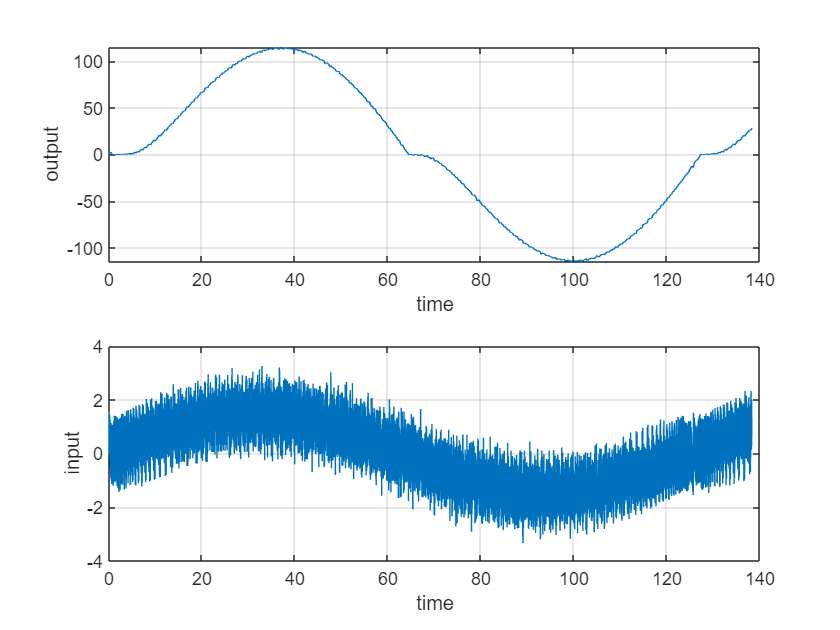

figure(1)
subplot(2,1,1)
plot(t,process_output(:,2))
xlabel('time')
ylabel('output')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input')
grid on

Calcolo i coefficienti di Fourier dell'uscita

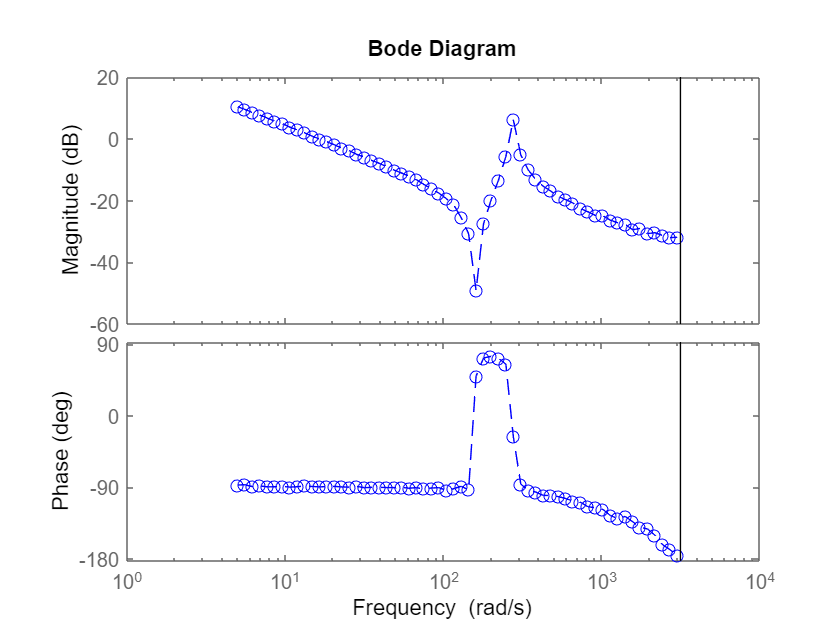

process_output_coef=fourierCoefficients(t,process_output(:,2),omega_portante,omega);
freq_resp=idfrd(process_output_coef./control_action_coef,omega,st); % Y(i*omega)/U(i*omega)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
figure(2)
h=bodeplot(freq_resp,'--o', bode_opts);

Stima modello (potrei farla a mano)

peso=ones(length(freq_resp.Frequency),1);
peso(freq_resp.Frequency<omega(1))=1e-5;
peso(freq_resp.Frequency>omega(end))=1e-5;
 
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
mc = ssest(freq_resp,3,opts);
md = ssest(freq_resp,3,'Ts',st,opts);

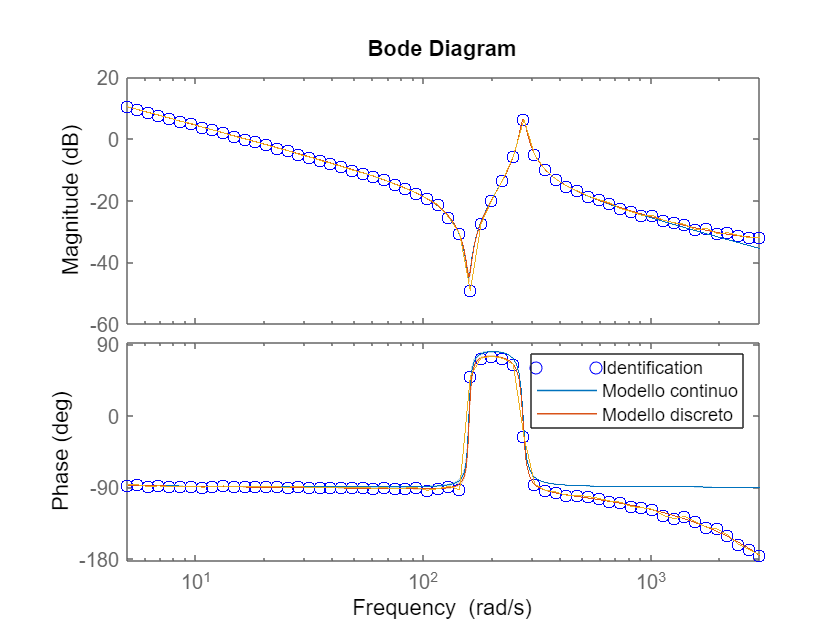

figure(3)


h=bodeplot(freq_resp,'o', bode_opts);
showConfidence(h,3)
hold on
bode(mc,md,freq_resp, bode_opts)
xlim([omega(1) omega(end)])


legend('Identification','Modello continuo','Modello discreto')